# Precision(P20)

% Load data
load C:\Users\Andrea\Desktop\MAGISTRALE\Anno1-sem2\SearchEngines\HWS\seupd2021-goldr\RUN\RUN2020\RunAnalysis\runtotonlyprec20.mat

measure_prec20 = runtotonlyprec20(1:49,:);
measure_prec20 = table2array(measure_prec20)

measure_prec20 =     0.4000    0.4000    0.4000    0.4500    0.4500
    0.2000    0.2000    0.2000    0.2000    0.2000
    0.2000    0.2000    0.2000    0.1500    0.1500
    0.3000    0.3000    0.3000    0.3500    0.3500
    0.2500    0.2500    0.2500    0.1000    0.1000
    0.3000    0.2500    0.3000    0.2000    0.2000
    0.3500    0.3500    0.3500    0.2500    0.3000
    0.2000    0.2000    0.2000    0.0500    0.0500
    0.3500    0.4000    0.3500    0.3500    0.3500
    0.2500    0.3500    0.2500    0.2500    0.2000



% remove the now useless ap matrix
clear runtotonlyprec20;

% the significance level
alpha = 0.05;

% the mean for each run across the topics
m_avg_prec20 = mean(measure_prec20);



% sort in descending order of mean score
[~, idx] = sort(m_avg_prec20, 'descend');

ogmyruns = ""

ogmyruns = ""

ogmyruns(1) = "run1";
ogmyruns(2) = "run2";
ogmyruns(3) = "run3";
ogmyruns(4) = "run4";
ogmyruns(5) = "run5";

myruns_prec20 = ogmyruns

myruns_prec20 = 1×5 string array
    "run1"    "run2"    "run3"    "run4"    "run5"



% re-order runs by descending mean of the measure
measure_prec20 = measure_prec20(:, idx);
myruns_prec20 = myruns_prec20(:, idx);


## One way ANOVA

% perform the ANOVA
[~, tbl_prec20, sts_prec20] = anova1(measure_prec20, myruns_prec20, 'off');

% display the ANOVA table
tbl_prec20

tbl_prec20 = 4×6 cell array
    {'Source' }    {'SS'    }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Columns'}    {[0.2246]}    {[  4]}    {[  0.0562]}    {[  4.1764]}    {[  0.0027]}
    {'Error'  }    {[3.2271]}    {[240]}    {[  0.0134]}    {0×0 double}    {0×0 double}
    {'Total'  }    {[3.4518]}    {[244]}    {0×0 double}    {0×0 double}    {0×0 double}


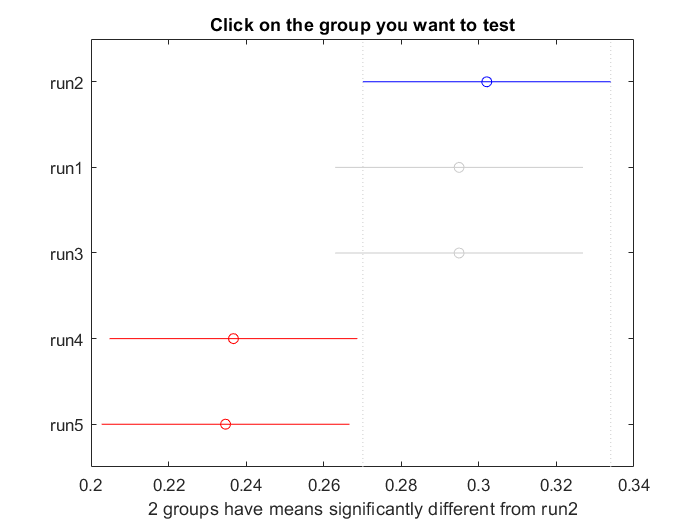


c = multcompare(sts_prec20, 'Alpha', alpha, 'Ctype', 'hsd'); 

c

c =     1.0000    2.0000   -0.0568    0.0071    0.0710    0.9981
    1.0000    3.0000   -0.0568    0.0071    0.0710    0.9981
    1.0000    4.0000    0.0014    0.0653    0.1292    0.0423
    1.0000    5.0000    0.0034    0.0673    0.1313    0.0330
    2.0000    3.0000   -0.0639         0    0.0639    1.0000
    2.0000    4.0000   -0.0057    0.0582    0.1221    0.0945
    2.0000    5.0000   -0.0037    0.0602    0.1241    0.0760
    3.0000    4.0000   -0.0057    0.0582    0.1221    0.0945
    3.0000    5.0000   -0.0037    0.0602    0.1241    0.0760
    4.0000    5.0000   -0.0619    0.0020    0.0659    1.0000


## Two way ANOVA

% perform the ANOVA
[~, tbl2_prec20, sts2_prec20] = anova2(measure_prec20, 1,'off');

% display the ANOVA table
tbl2_prec20

tbl2_prec20 = 5×6 cell array
    {'Source' }    {'SS'    }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[0.2246]}    {[  4]}    {[  0.0562]}    {[ 30.9511]}    {[6.9140e-20]}
    {'Rows'   }    {[2.8788]}    {[ 48]}    {[  0.0600]}    {[ 33.0545]}    {[2.5002e-70]}
    {'Error'  }    {[0.3484]}    {[192]}    {[  0.0018]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[3.4518]}    {[244]}    {0×0 double}    {0×0 double}    {0×0 double  }


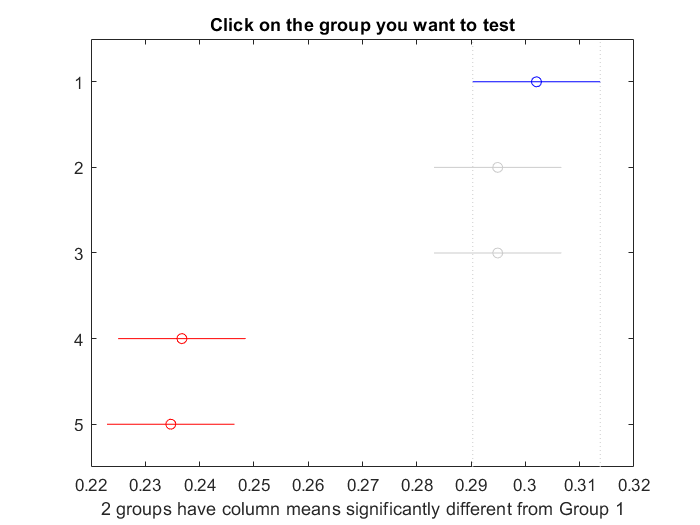


c2 = multcompare(sts2_prec20, 'Alpha', alpha, 'Ctype', 'hsd'); 

c2

c2 =     1.0000    2.0000   -0.0163    0.0071    0.0306    0.9214
    1.0000    3.0000   -0.0163    0.0071    0.0306    0.9214
    1.0000    4.0000    0.0418    0.0653    0.0888    0.0000
    1.0000    5.0000    0.0439    0.0673    0.0908    0.0000
    2.0000    3.0000   -0.0235         0    0.0235    1.0000
    2.0000    4.0000    0.0347    0.0582    0.0816    0.0000
    2.0000    5.0000    0.0367    0.0602    0.0837    0.0000
    3.0000    4.0000    0.0347    0.0582    0.0816    0.0000
    3.0000    5.0000    0.0367    0.0602    0.0837    0.0000
    4.0000    5.0000   -0.0214    0.0020    0.0255    0.9993


## BoxPlot

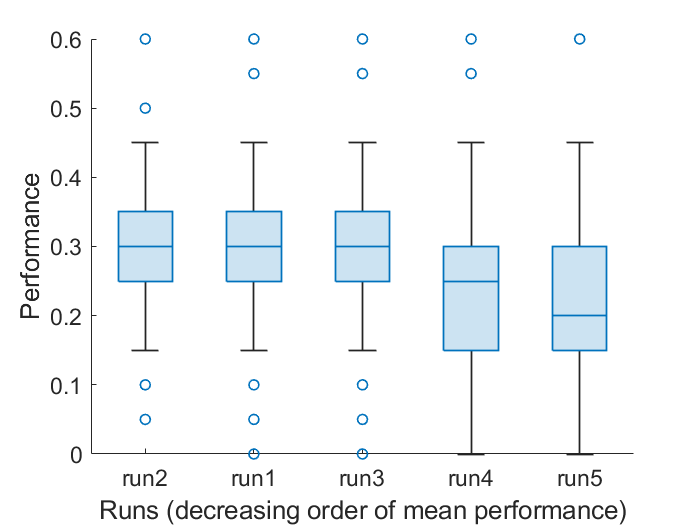

% Compute the mean performance of each run across topics

m_prec20 = mean(measure_prec20);
myruns3 = ogmyruns;

% sort in descending order of mean score
[~, idx] = sort(m_prec20, 'descend');

% re-order runs by descending mean of the measure
% needed to have a more nice looking box plot
measure_prec20 = measure_prec20(:, idx);
myruns3 = myruns_prec20(:,idx);

figure

% show the box plot
boxchart(measure_prec20)

%hold on

% plot the mean on top of the box plot
%plot (m, ':x', "MarkerSize", 10, "LineWidth", 2)

% adjust tick labels on x-axis, y-axis range, and font size
ax = gca;
ax.FontSize = 14;
ax.XTickLabel = myruns3;

xlabel("Runs (decreasing order of mean performance)")
ylabel("Performance")

Run run1 vs run2: p-value 0.367517

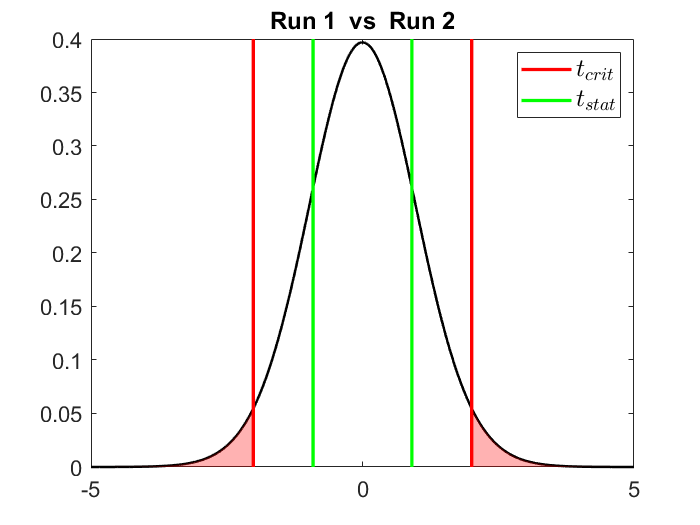

Run run1 vs run3: p-value NaN

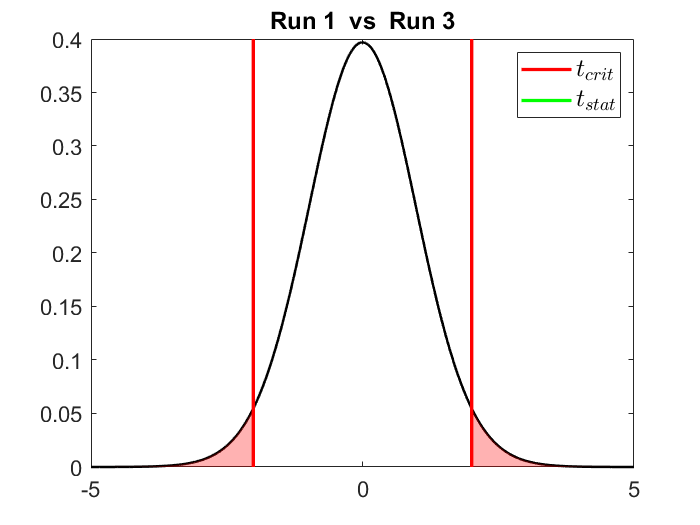

Run run1 vs run4: p-value 0.000000

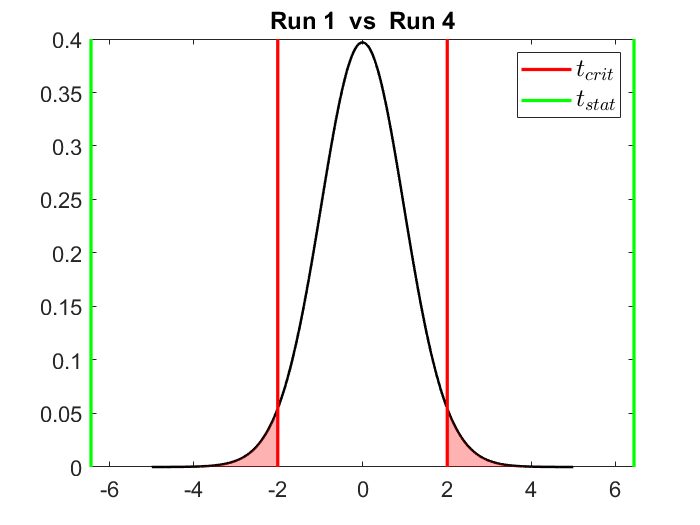

Run run1 vs run5: p-value 0.000000

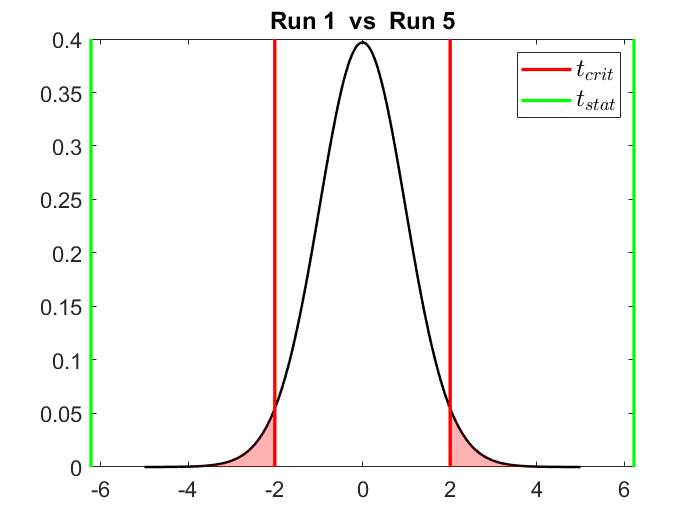

Run run2 vs run3: p-value 0.367517

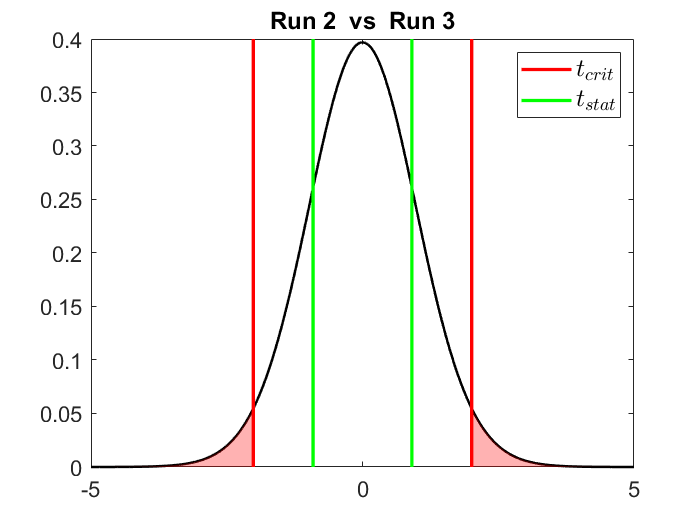

Run run2 vs run4: p-value 0.000000

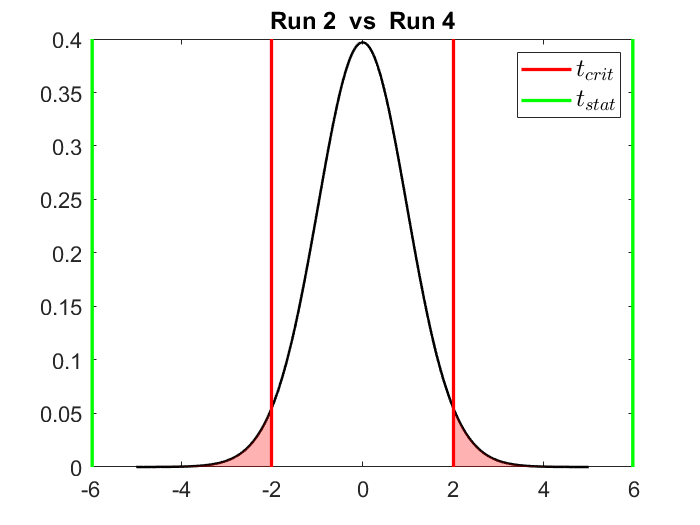

Run run2 vs run5: p-value 0.000000

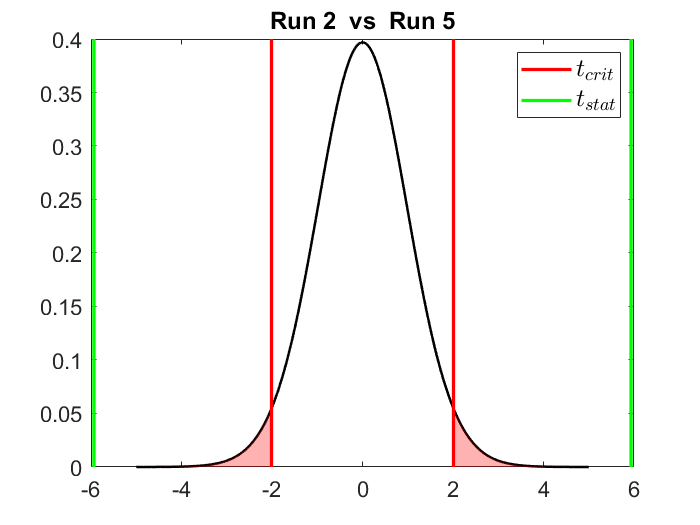

Run run3 vs run4: p-value 0.000000

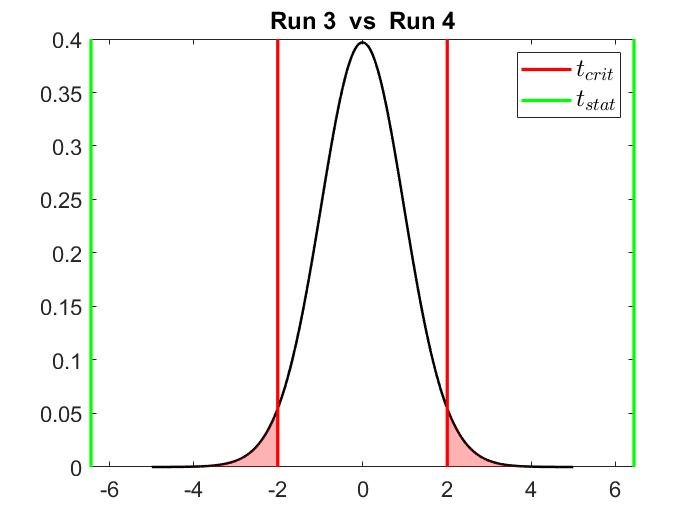

Run run3 vs run5: p-value 0.000000

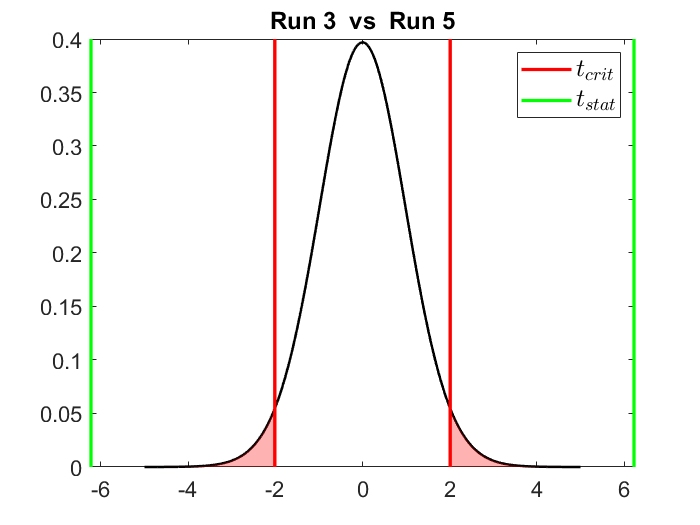

Run run4 vs run5: p-value 0.642165

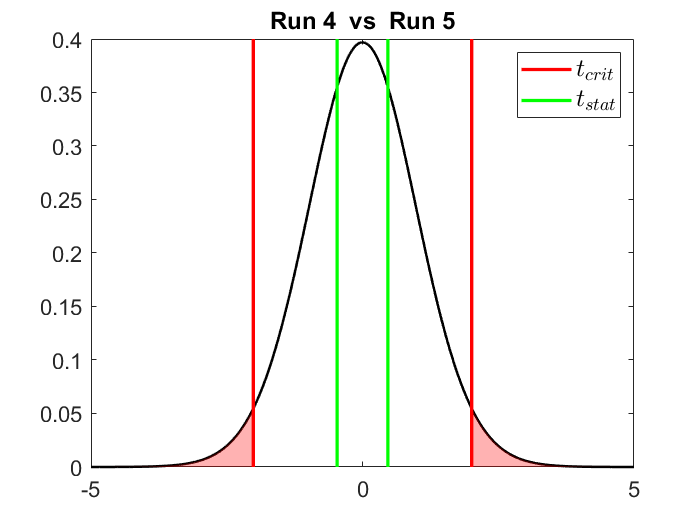

newmeasure_p = measure_prec20(:, [2,1,3,4,5]);
for r1 = 1:length(myruns3)
    for r2 = 1:length(myruns3)
        if r1 < r2
            %tstudnet comparisons
            [~, p] = ttest(newmeasure_p(:, r1), newmeasure_p(:, r2));
            %p(isnan(p))=0;
            fprintf("Run %s vs %s: p-value %f", ogmyruns(r1), ogmyruns(r2), p)
            df = length(newmeasure_p) - 1;
            tCrit = tinv(1 - 0.05/2, df);
            tRuns = tinv(1 - p/2, df);
            
            %if p == 0
             %   tRuns = 10;
            %else
               % tRuns = tinv(1 - p/2, df);
                %fprintf("tRuns: " + tRuns)
            %end
            

            % t distribution 
            ar = -5:.01:5;
            ts = tpdf(ar, df);

            % find where we are above and below tCrit
            idx1 = ar >= tCrit;
            idx2 = ar <= -tCrit;
            
            figure

            plot(ar, ts, "LineWidth", 1.5, "Color", "k");
            
            hold on

            % plot two vertical lines corresponding to tCrit
            h(1) = plot([tCrit tCrit], get(gca, "ylim"), "Color", "r", "LineWidth", 2, "LineStyle", "-");
            plot([-tCrit -tCrit], get(gca, "ylim"), "Color", "r", "LineWidth", 2, "LineStyle", "-");

            % color the area under the t distribution above and below tCrit
            area(ar(idx1), ts(idx1) , "FaceColor", "r", "FaceAlpha", 0.3, "EdgeColor", "none");
            area(ar(idx2), ts(idx2), "FaceColor", "r", "FaceAlpha", 0.3, "EdgeColor", "none");
            
            h(2) = plot([tRuns tRuns], get(gca, "ylim"), "Color", "g", "LineWidth", 2, "LineStyle", "-");
            plot([-tRuns -tRuns], get(gca, "ylim"), "Color", "g", "LineWidth", 2, "LineStyle", "-");
            %xline(tRuns, "Color", "g", "LineWidth", 2);

            ax = gca;
            ax.FontSize = 13;
            title(['Run ',num2str(r1),'  vs  Run ',num2str(r2)])
            
            lgnd = legend([h(1), h(2)], ["$t_{crit}$", "$t_{stat}$"], "Interpreter", "Latex");
            lgnd.FontSize = 15;
            
            %fprintf("%d - %d \n", r1, r2)
            if r2 == 5
                break
            end
        end
    end
end